# [Sonar Detection](http://apmonitor.com/pds/index.php/Main/SonarDetection)

Sonar (sound navigation and ranging) uses sound waves to detect objects, similar to how a bat uses echo-location to navigate, and detect objects. It is the same principle with seismic data for non-invasive underground exploration of geologic formations to locate oil or gas reserves.

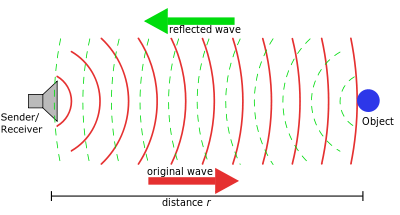

**Background**

A data set of sonar returns is available for rock and metal pipe with samples taken from different angles and locations. The data was collected in a laboratory under controlled conditions as a case study for detecting underground pipe. There are 111 labeled sets for the metal cylinder (pipe) and 97 sonar patterns from rocks with similar conditions. Each sample is a set of 60 numbers between 0 and 1 that represents the integrated energy within a distinct frequency band and for a given time period.

Although this case study is specific to detecting differences between metal pipe and rock, it is similar to detection of other underground features such as tunnels, mines, aquifers, and fluid-filled pipelines.

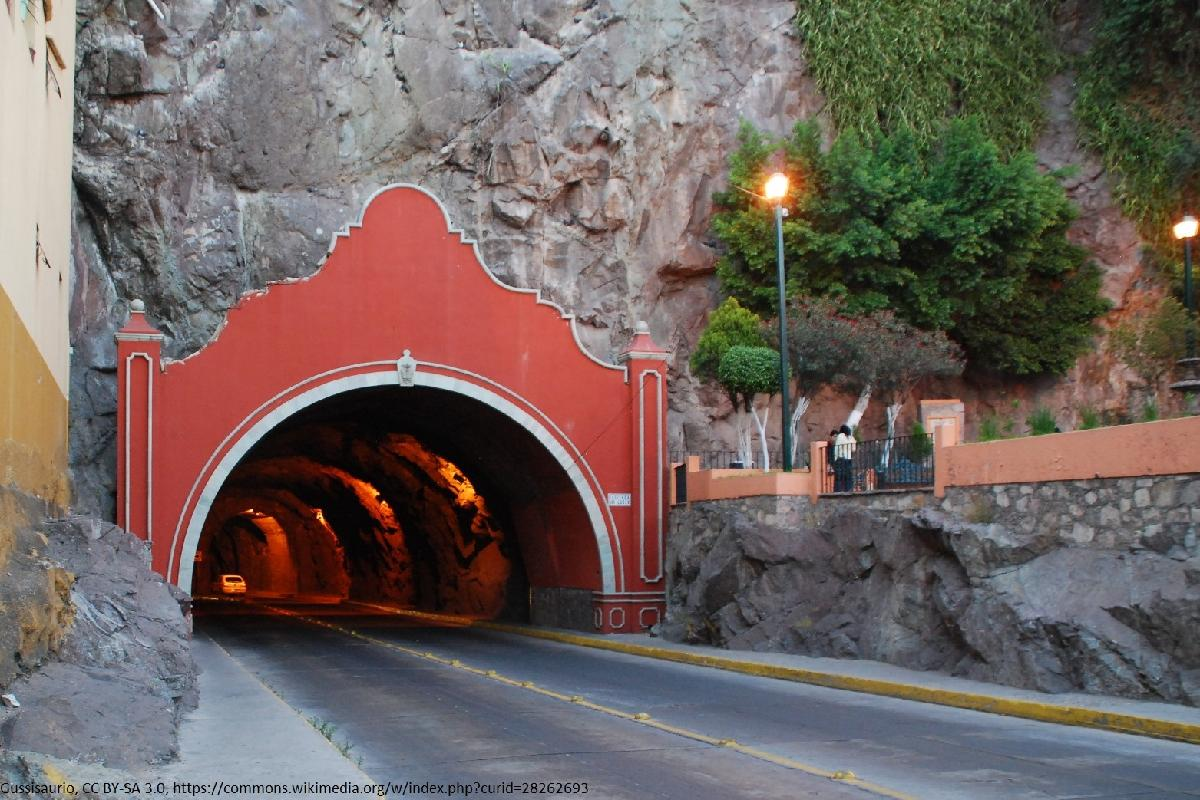

This case study focuses on classification using the 60 attributes (sonar returns) to determine whether object is rock or a metal pipe. The label associated with each record contains the letter *R* if the object is a rock and *M* if it is a metal pipe. [One-hot encoding](https://en.wikipedia.org/wiki/One-hot) is needed to translate this character label into a binary representation (1 or 2) for classification.

clear
url = 'http://apmonitor.com/pds/uploads/Main/sonar_detection.txt';
data = readtable(url);

% One-hot encode 'Class' (2 is 'Metal', 1 is 'Rock')
data.Class = categorical(data.Class, {'R', 'M'}, {'1', '2'});
data.Class = double(data.Class);

## Classification: Detect Pipe or Rock with Sonar Data

**Read Data**

`Display 10 random rows with datasample(data,10).`

data = readtable('http://apmonitor.com/pds/uploads/Main/sonar_detection.txt');
disp(datasample(data,10))

     Ang1      Ang2      Ang3      Ang4      Ang5      Ang6      Ang7      Ang8      Ang9     Ang10     Ang11     Ang12     Ang13     Ang14     Ang15     Ang16     Ang17     Ang18     Ang19     Ang20     Ang21     Ang22     Ang23     Ang24     Ang25     Ang26     Ang27     Ang28     Ang29     Ang30     Ang31     Ang32     Ang33     Ang34     Ang35     Ang36     Ang37  

**Data Visualization**

Create plots to visualize the data.

figure('Position', [0, 0, 1200, 800]);

%remove "Class" from the data set
datanoclass= data(:,1:60);

arraydatanoclass = table2array(datanoclass)

arraydatanoclass =     0.0200    0.0371    0.0428    0.0207    0.0954    0.0986    0.1539    0.1601    0.3109    0.2111    0.1609    0.1582    0.2238    0.0645    0.0660    0.2273    0.3100    0.2999    0.5078    0.4797    0.5783    0.5071    0.4328    0.5550    0.6711    0.6415    0.7104    0.8080    0.6791    0.3857    0.1307    0.2604    0.5121    0.7547    0.8537    0.8507    0.6692    0.6097    0.4943    0.2744    0.0510    0.2834    0.2825    0.4256    0.2641    0.1386    0.1051    0.1343    0.0383    0.0324
    0.0453    0.0523    0.0843    0.0689    0.1183    0.2583    0.2156    0.3481    0.3337    0.2872    0.4918    0.6552    0.6919    0.7797    0.7464    0.9444    1.0000    0.8874    0.8024    0.7818    0.5212    0.4052    0.3957    0.3914    0.3250    0.3200    0.3271    0.2767    0.4423    0.2028    0.3788    0.2947    0.1984    0.2341    0.1306    0.4182    0.3835    0.1057    0.1840    0.1970    0.1674    0.0583    0.1401    0.1628    0.0621    0.0203    0.0530    0.0742

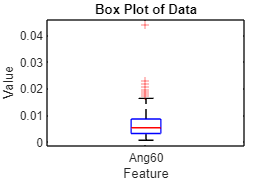


% Boxplots of data, then elimination of outliers
for i=1:60
    boxplot(arraydatanoclass(:,i), 'Labels', data.Properties.VariableNames(i), 'Whisker', 1.5);
    title('Box Plot of Data');
    xlabel('Feature');
    ylabel('Value');
end

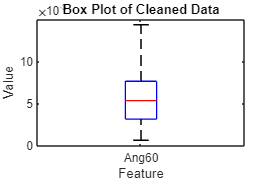


% Remove outliers
for i=1:60
    % find outliers
    median_val = median(arraydatanoclass(:,i));
    std_val = std(arraydatanoclass(:,i));
    outliers = (arraydatanoclass(:,i) > median_val + 2*std_val) | (arraydatanoclass(:,i) < median_val - 2*std_val);
    
    % replace outliers with median
    arraydatanoclass(outliers,i) = median_val;
end

% Boxplots of cleaned data
for i=1:60
    boxplot(arraydatanoclass(:,i), 'Labels', data.Properties.VariableNames(i), 'Whisker', 1.5);
    title('Box Plot of Cleaned Data');
    xlabel('Feature');
    ylabel('Value');
end

% Density plots of cleaned data. Takes a long time to run
%for i=1:60
    %figure;
    %ksdensity(arraydatanoclass(:,i));
    %title(['Density Plot of Figure', num2str(i)]);
    %xlabel('Feature');
    %ylabel('Value');
%end

% Replace original data with cleaned data
data(:, 1:end-1) = array2table(arraydatanoclass)

data = 208×61 table
     Ang1      Ang2      Ang3      Ang4       Ang5      Ang6       Ang7       Ang8      Ang9      Ang10     Ang11      Ang12      Ang13     Ang14     Ang15     Ang16     Ang17     Ang18     Ang19     Ang20     Ang21     Ang22     Ang23     Ang24     Ang25     Ang26     Ang27     Ang28     Ang29      Ang30     Ang31     Ang32     Ang33      Ang34      Ang35      Ang36


% Show the grouping by Class
class_sizes = groupsummary(data,"Class");
counts = categorical(class_sizes.Class)

counts = 2×1 categorical array
     M 
     R 


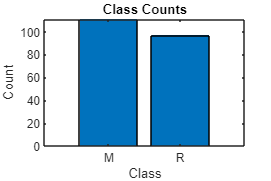

bar(counts,class_sizes.GroupCount);
title('Class Counts');
xlabel('Class');
ylabel('Count');

## Correlation Matrix

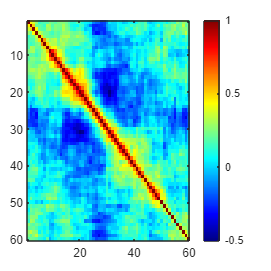

% Calculate the correlation matrix
corr_matrix = corr(table2array(data(:,1:60)));

% Create the figure and the axis object
fig = figure();
ax = axes();

% Plot the correlation matrix using the 'image' function
image(corr_matrix, 'CDataMapping', 'scaled', 'Parent', ax);

% Set the axis limits and the colormap
ax.XLim = [0.5 size(corr_matrix, 2) + 0.5];
ax.YLim = [0.5 size(corr_matrix, 1) + 0.5];
colormap('jet');

% Add a colorbar and set the figure size
colorbar();
fig.Position(3:4) = [800 800];

% Save the figure and show it
saveas(fig, 'sonar_correlation.png');

What insights do you gain from the data visualization and exploration? In particular, comment on the presence of uniform data distributions, outliers, missing data, and other data quality issues.

**Scale Data**

Scale data with a [Standard Scalar](https://scikit-learn.org/stable/modules/generated/sklearn.preprocessing.StandardScaler.html) so that all features (sonar returns) are scaled.

X = table2array(data(:,1:end-1));

% Standardize data
X = (X - mean(X)) ./ std(X);


% Convert back to table and set column names
data_std = array2table(X,"VariableNames",data.Properties.VariableNames(:,1:end-1));
data_std = horzcat(data_std, data(:,{'Class'}))

data_std = 208×61 table
      Ang1         Ang2         Ang3         Ang4         Ang5         Ang6         Ang7         Ang8        Ang9         Ang10       Ang11       Ang12       Ang13       Ang14        Ang15       Ang16        Ang17       Ang18       Ang19       Ang20        Ang21       Ang22        Ang23       Ang24       Ang25        Ang26       Ang27       Ang28       Ang29       Ang30       Ang31        Ang32        Ang33     

**Best Features**

What are the factors that are most correlated or influential for predicting pipe versus rock. Manually produce a ranked list.

k = 5;
y = data.Class;
X_scores = fscmrmr(X, y); % Rank features by mutual information and redundancy measures
[~, idx] = sort(X_scores, 'descend');
k_best = X(:, idx(1:k)); % Select the top k features

column_names = data_std.Properties.VariableNames;

for i = 1:k
    fprintf('%s\n', column_names{idx(i)})
end

Ang32
Ang12
Ang34
Ang35
Ang60


**Train / Test Split**[**¶**](http://localhost:8888/notebooks/Downloads/Sonar_Detection_Solution.ipynb#Train-/-Test-Split)

Split the data into **Test** and **Train** sets. Randomly select values that split the data into a train (80%) and test (20%) set.

[trainInd,valInd,testInd] = dividerand (height(data),0.8,0,0.2)

trainInd =      1     2     3     5     6     8    10    11    12    13    14    15    16    17    18    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    42    43    44    45    46    48    49    50    51    52    54    55    56    57



valInd =

  1×0 empty double row vector



testInd =      4     7     9    19    41    47    53    60    67    72    88    89    92    93   101   105   109   113   124   126   128   129   136   142   144   145   146   149   152   155   166   170   172   185   186   188   197   198   202   203   205   208


X_train= data(trainInd,:)

X_train = 166×61 table
     Ang1      Ang2      Ang3      Ang4       Ang5      Ang6       Ang7       Ang8      Ang9      Ang10     Ang11      Ang12      Ang13     Ang14     Ang15     Ang16     Ang17     Ang18     Ang19     Ang20     Ang21     Ang22     Ang23     Ang24     Ang25     Ang26     Ang27     Ang28     Ang29      Ang30     Ang31     Ang32     Ang33      Ang34      Ang35      Ang36

X_test = data(testInd,:)

X_test = 42×61 table
     Ang1      Ang2      Ang3      Ang4       Ang5      Ang6       Ang7       Ang8      Ang9     Ang10     Ang11     Ang12      Ang13     Ang14     Ang15     Ang16     Ang17     Ang18      Ang19     Ang20     Ang21     Ang22     Ang23     Ang24     Ang25     Ang26     Ang27     Ang28     Ang29      Ang30     Ang31     Ang32     Ang33      Ang34      Ang35      Ang36

Classification: Use 8 classification methods. 

Methods and documentation can be found in the [Mathworks classification documentation](https://www.mathworks.com/help/stats/classification.html).

The Classification Learner app can also be used. Access it from the "Apps" tab in MATLAB or open it by running "classificationLearner" in the Live Editor.

t = tiledlayout(4, 2, 'TileSpacing', 'Compact');

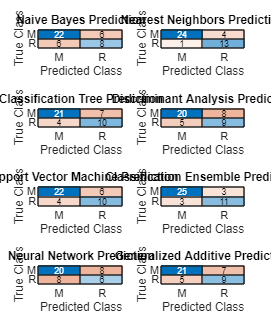

figure('Position', [0, 0, 1000, 1200], 'Resize', 'off');

% Naive Bayes
nb = fitcnb(X_train, 'Class');
labels = predict(nb, X_test);
nexttile;
confusionchart(X_test.Class, labels);
title("Naive Bayes Prediction");

% Nearest Neighbors
knn = fitcknn(X_train, 'Class');
labels = predict(knn, X_test);
nexttile;
confusionchart(X_test.Class, labels);
title("Nearest Neighbors Prediction");

% Classification Tree
tree = fitctree(X_train, 'Class');
labels = predict(tree, X_test);
nexttile;
confusionchart(X_test.Class, labels);
title("Classification Tree Prediction");

% Discriminant Analysis
disc = fitcdiscr(X_train, 'Class');
labels = predict(disc, X_test);
nexttile;
confusionchart(X_test.Class, labels);
title("Discriminant Analysis Prediction");

% Support Vector Machine Classification
vect = fitcsvm(X_train, 'Class');
labels = predict(vect, X_test);
nexttile;
confusionchart(X_test.Class, labels);
title("Support Vector Machine Prediction");

% Classification Ensemble
ensemble = fitcensemble(X_train, 'Class');
labels = predict(ensemble, X_test);
nexttile;
confusionchart(X_test.Class, labels);
title("Classification Ensemble Prediction");

% Neural Network
nn = fitcnet(X_train, 'Class');
labels = predict(nn, X_test);
nexttile;
confusionchart(X_test.Class, labels);
title("Neural Network Prediction");

% Generalized Additive Model
genadd = fitcgam(X_train, 'Class');
labels = predict(genadd, X_test);
nexttile;
confusionchart(X_test.Class, labels);
title("Generalized Additive Prediction");